clear;clc;
startTime = datetime(2020,1,11,14,50,0);
stopTime = startTime + days(3);
sampleTime = 60;

sc = satelliteScenario(...
    startTime,stopTime,sampleTime);

Add a satellite scenario

sat = satellite(sc,"leoSatelliteConstellation.tle");
orbitProp = sat(1).OrbitPropagator

orbitProp = "sgp4"

gainToNoiseTemperatureRatio = 5;                                                        % dB/K
systemLoss = 3; 
frequency = 27e9;                                                                     % Hz
power = 20;                                                                           % dBW
bitRate = 20;                                                                         % Mbps
dishDiameter = 0.5;                                                                    % meters
apertureEfficiency = 0.5;
elements = orbitalElements(sat(1))

elements = struct with fields:
                       MeanMotion: 0.0589
                     Eccentricity: 9.1450e-04
                      Inclination: 55.2591
    RightAscensionOfAscendingNode: 2.0982
              ArgumentOfPeriapsis: 230.1420
                      MeanAnomaly: 118.4821
                           Period: 6.1086e+03
                            Epoch: 04-May-2020 18:45:35
                            BStar: 9.4230e-05


%   Add transmitters and receivers
gimbalrxSat = [];
gimbaltxSat = [];
rxSat = [];
txSat = [];
for i=1:length(sat.transmitter)
    gimbaltxSat = [gimbaltxSat gimbal(sat(i))];
    txSat = [txSat transmitter(gimbaltxSat(i),Name="Satellite Transmitter "+i,Frequency=frequency, ...
    power=power,BitRate=bitRate,SystemLoss=systemLoss)];
    gaussianAntenna(txSat(i),DishDiameter=dishDiameter,ApertureEfficiency=apertureEfficiency);
end

for i=1:length(sat.receiver)
    gimbalrxSat = [gimbalrxSat gimbal(sat(i))];
    rxSat = [rxSat receiver(gimbalrxSat(i),Name="Satellite Receiver "+i,GainToNoiseTemperatureRatio= ...
    gainToNoiseTemperatureRatio,SystemLoss=systemLoss)];
    gaussianAntenna(rxSat(i),DishDiameter=dishDiameter,ApertureEfficiency=apertureEfficiency);
end

if ~isempty(sat.Transmitters)
    disp('Satellite can transmit.');
else
    disp('Satellite cannot transmit.');
end

Satellite can transmit.


if ~isempty(sat.Receivers)
    disp('Satellite can receive.');
else
    disp('Satellite cannot receive.');
end

Satellite can receive.


Add a ground station

name = "Lamia Base Station";
lat=38.875941904578895;
lon=22.437526584061686;
gs1 = groundStation(sc,...
    Name=name,Latitude=lat,Longitude=lon);
gimbalrxGs = gimbal(gs1);
gimbaltxGs = gimbal(gs1);
rxGs = receiver(gimbalrxGs,Name="Ground Station Receiver");
txGs = transmitter(gimbaltxGs,Name="Ground Station Transmitter");

latitude = 52.2294963;                                              % degrees
longitude = 0.1487094;                                              % degrees
gs2 = groundStation(sc,latitude,longitude,Name="Ground Station 2");
% 
for i=1:length(gimbaltxSat)
    pointAt(gimbaltxSat(i),gs2);
    pointAt(gimbalrxSat(i),gs1);
end

gimbalgs1 = gimbal(gs1);
gimbalgs2 = gimbal(gs2);
frequency = 30e9;                                                                          % Hz
power = 40;                                                                                % dBW
bitRate = 20;                                                                              % Mbps
txGs1 = transmitter(gimbalgs1,Name="Ground Station 1 Transmitter",Frequency=frequency, ...
        Power=power,BitRate=bitRate);

requiredEbNo = 14;                                                                     % dB
rxGs2 = receiver(gimbalgs2,Name="Ground Station 2 Receiver",RequiredEbNo=requiredEbNo);

% dishDiameter = 5;                                % meters
% gaussianAntenna(txGs1,DishDiameter=dishDiameter);
% gaussianAntenna(rxGs2,DishDiameter=dishDiameter);
% 
% pointAt(gimbalgs1,sat);
% pointAt(gimbalgs2,sat);

Add an access analysis and visualize the scenario

ac = access(sat,gs1);
%   time to analyze the access intervals
intv = accessIntervals(ac)

intv = 907×8 table
       Source               Target           IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    _____________    ____________________    ______________    ____________________    ____________________    ________    __________    ________

    "Satellite 1"    "Lamia Base Station"           1          11-Jan-2020 18:56:00    11-Jan-2020 19:05:00      540            3            3   
    "Satellite 1"    "Lamia Base Station"           2          11-Jan-2020 20:38:00    11-Jan-2020 20:53:00      900            4            4   
    "Satellite 1"    "Lamia Base Station"           3          11-Jan-2020 22:24:00    11-Jan-2020 22:39:00      900        

Visualize the scenario. Set the camera positioning to bring all satellites that have access to the ground station into view!

% v = satelliteScenarioViewer(sc);
% campos(v,...
%     29,...
%     -19,...
%     7.3e7);
%   what are those values?

Calculate Latency and Rate of Change of Latency

lnk = link(txGs1,rxSat,txSat,rxGs2)

lnk =   1x40 Link array with properties:

    Sequence
    LineWidth
    LineColor


linkIntervals(lnk)


ans =

  0×8 empty table

    Source    Target    IntervalNumber    StartTime    EndTime    Duration    StartOrbit    EndOrbit
    ______    ______    ______________    _________    _______    ________    __________    ________




[delay,time] = latency(sat,gs1);

Plotting the propagation delay corresponding to the first satellite. 

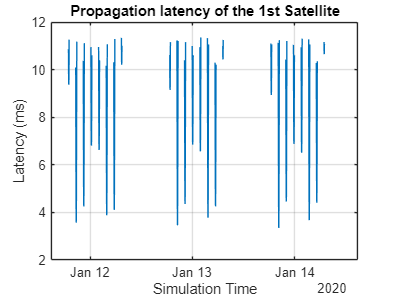

plot(time,delay(1,:)*1000); % plot in ms
xlim([time(1) time(end)]);
title("Propagation latency of the 1st Satellite");
xlabel("Simulation Time");
ylabel("Latency (ms)");
grid on;